# 1CWK50 Artificial Intelligence

## **Filesize-based features**

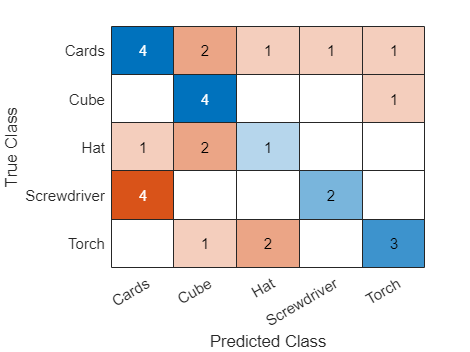

% check the dataset is present:
if ~exist('MerchData.csv', 'file')
    error('Error: Data set MerchData not fond, check the directory.');
end
rng(0); % Good practice to reseed random generator in order to compare results

% creates a cell array by reading column-oriented data from a merchData.
M = readcell('MerchData.csv');
%I removed first raw as it cointains description of columns such as 'filesize'and 'object'
M(1, :) = [];

% we shuffle the rows so when we split the data, testing and training tables
% have variety of objects from the whole table 
M = M(randperm(size(M,1)), :);

% get 40 perccent of data and ensure its rounded number
table = round(0.4*size(M,1));

% split data into training and testing using variable table, 
% our AI will train on data_train and tested on data_test
data_test = M(1:1:table,:);
data_train = M(table+1:1:end,:);

% In the table provided second colum is categorical, it has a names of an object :
% I will use it to split the table into labels and examples
label_index = 2;

% I split data_test in two parts test_labels that will contain labels
% and test_examples that will contain filesize info
% I will use test labels for confusion matrix to test prediction
% and test examples to get predictions using trained classification knn
test_labels = categorical(data_test(:, label_index));
test_examples = cell2mat(data_test(:, 1:end~=label_index));

% Same operation as before but splitting train label in this case
% and it will be used to train knn instead of testing
train_labels = categorical(data_train(:, label_index));
train_examples = cell2mat(data_train(:, 1:end~=label_index));

% training classification model using fitcknn using examples and labels
% extracted earlier and hyperparameter oof knn set to 3 as it is more accurate
% I am doing this to use it earlier against test data set.

% inbuilt function
%m_knn = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
m_knn3 = knn_fit(train_examples, train_labels, 3);

% now we predict object by filesize using knn classification trained
% earlier, i will use it later to demonstrate how well did knn predict
% labels

% inbuilt function
%predictions = predict(m_knn, test_examples);
predictions = knn_predict(m_knn3, test_examples);

% return confusion matrix using known group and predicted 
% we will use it later to calculate precision percentage
c = confusionmat(test_labels, predictions);

% creating visual representation of how well did predictions work
confusionchart(test_labels, predictions);


% calcuating percentage of accuracy using data extracted from confustion
% matrix
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 46.6667

## Brightness-based features 

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('Error: Data set MerchData not fond, check the directory.');
end

rng(0); % Good practice to reseed random generator in order to compare results

% loading image datastore MerchData such so folders are included and folder
% names as well
imds = imageDatastore('MerchData','IncludeSubfolders', true, 'LabelSource','foldernames');

% splitting data store into 0.6 and 0.4, for training and testing purposes
% make sure date is shuffled and rng is reseeded
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

% creating train example in order to train knn later
train_examples = [];
% go through each image (using .read()) in training until it has one
while hasdata(training)
    % using modified get_brightness function that uses my_im2grey
    % and adding the output to the end of train examples
    train_examples(end+1,:) = get_brightness(training.read());
end
% extracting labels from training table 
% to use it for knn training
train_labels = training.Labels;

% same process as for training
test_examples = [];
while hasdata(testing)
    % using modified get_brightness function that uses my_im2grey
    test_examples(end+1,:) = get_brightness(testing.read());
end
% extracting labels from training table 
% to use it for knn testing
test_labels = testing.Labels;

% training classification model using fitcknn using examples and labels
% extracted earlier and hyperparameter to set to 3 as it is more accurate
% I am doing this to use it earlier against test data set.
%m_knn = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
m_knn3 = knn_fit(train_examples, train_labels, 3);

% now we predict object by filesize using knn classification trained
% earlier, i will use it later to demonstrate how well did knn predict
%predictions = predict(m_knn, test_examples);
predictions = knn_predict(m_knn3, test_examples);

% return confusion matrix using known group and predicted 
% we will use it later to calculate precision percentage
c = confusionmat(test_labels, predictions)

c =      2     4     0     0     0
     2     1     2     1     0
     2     0     4     0     0
     2     2     1     1     0
     0     0     1     0     5


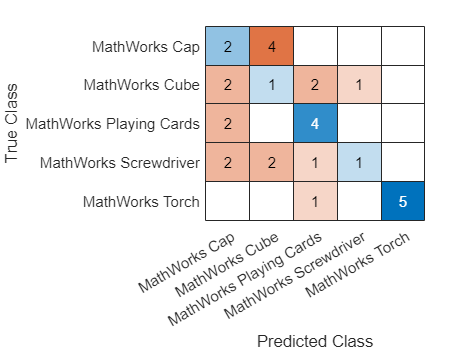


% creating visual representation of how well did predictions work
confusionchart(test_labels, predictions);


% calcuating percentage of accuracy using data extracted from confustion
% matrix
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 43.3333

## Edge-based features 

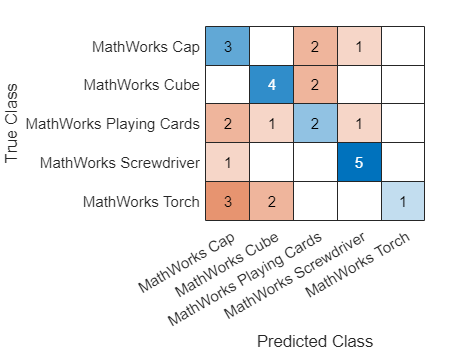

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('Error: Data set MerchData not fond, check the directory.');
end

rng(0); % Good practice to reseed random generator in order to compare results

% loading image datastore MerchData such so folders are included and folder
% names as well
imds = imageDatastore('MerchData','IncludeSubfolders', true, 'LabelSource','foldernames');

% splitting data store into 0.6 and 0.4, for training and testing purposes
% make sure date is shuffled and rng is reseeded
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');


% creating train example in order to train knn later
train_examples = [];

% go through each image until it has one
while hasdata(training)
    % my function converts images from training into greyscale using
    % my_im2grey and gets edges data, then adding it to the end of training
    % example
    train_examples(end+1,:) = get_edges(training.read());
end
% extracting labels from training table 
% to use it for knn training
train_labels = training.Labels;

% same process as for training
test_examples = [];
while hasdata(testing)
    % my function converts images from testing into greyscale using
    % my_im2grey and gets edges data, then adding it to the end of testing
    % example
   test_examples(end+1,:) = get_edges(testing.read());
end
% extracting labels from training table 
% to use it for knn testing
test_labels = testing.Labels;

% training classification model using fitcknn using examples and labels
% extracted earlier and hyperparameter to set to 3 as it is more accurate
% I am doing this to use it earlier against test data set.
%m_knn = fitcknn(train_example, train_labels , 'NumNeighbors', 3);
m_knn3 = knn_fit(train_examples, train_labels, 3);

% now we predict object by filesize using knn classification trained
% earlier, i will use it later to demonstrate how well did knn predict
%predictions = predict(m_knn, test_examples);
predictions = knn_predict(m_knn3, test_examples);

% return confusion matrix using known group and predicted 
% we will use it later to calculate precision percentage
c = confusionmat(test_labels, predictions);

% creating visual representation of how well did predictions work
confusionchart(test_labels, predictions);


% calcuating percentage of accuracy using data extracted from confustion
% matrix
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 50

## HOG1 -based features 

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('Error: Data set MerchData not fond, check the directory.');
end

rng(0); % Good practice to reseed random generator in order to compare results

% loading image datastore MerchData such so folders are included and folder
% names as well
imds = imageDatastore('MerchData','IncludeSubfolders', true, 'LabelSource','foldernames');

imds =   ImageDatastore with properties:

                       Files: {
                              '/MATLAB Drive/MerchData/MerchData/MathWorks Cap/Hat_0.jpg';
                              '/MATLAB Drive/MerchData/MerchData/MathWorks Cap/Hat_123.jpg';
                              '/MATLAB Drive/MerchData/MerchData/MathWorks Cap/Hat_148.jpg'
                               ... and 72 more
                              }
                     Folders: {
                              '/MATLAB Drive/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 72 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


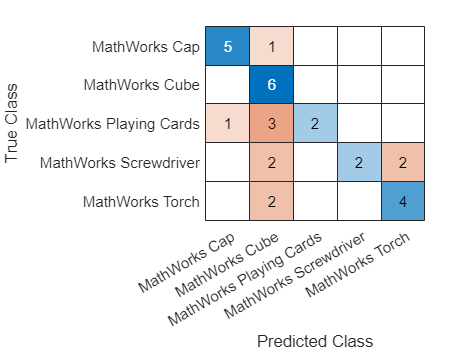


% splitting data store into 0.6 and 0.4, for training and testing purposes
% make sure date is shuffled and random number generator is reseeded
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

% creating train example in order to train knn later
train_example = [];

while hasdata(training)

    % i have done major progress in my_extractHOGFeatures please check the
    % file, but could not get exact same result



    % turning the image into grey scale to make it easier to work
    % and extract hog features intakes greyscale image
    im = im2gray(training.read());
    % extracting histograms of oriented gradient, 
    % from it with a patch size of 16*16 pixels
    CELLSIZE = [16 16];
    [h] = extractHOGFeatures(im, 'CellSize', CELLSIZE, ...
    'BlockSize', [floor(size(im,1)/CELLSIZE(1)) floor(size(im,2)/CELLSIZE(2))], ...
    'UseSignedOrientation', true);
   
    % add it to exicting table of train_example
    train_example(end+1,:) = h;
end
train_labels = training.Labels;

test_examples = [];
while hasdata(testing)
    % turning the image into grey scale to make it easier to work
    % and extract hog features intakes greyscale image
    im = my_im2gray(testing.read());
    % patch size of 16*16 pixels
    CELLSIZE = [16 16];
    [h] = extractHOGFeatures(im, 'CellSize', CELLSIZE, ...
    'BlockSize', [floor(size(im,1)/CELLSIZE(1)) floor(size(im,2)/CELLSIZE(2))], ...
    'UseSignedOrientation', true);
   
    % usually, we’ll move our feature extraction
    % work out into its own separate function:
    test_examples(end+1,:) = h;
end
test_labels = testing.Labels;
% write your code on the lines below:
%m_knn = fitcknn(train_example, train_labels , 'NumNeighbors', 3);
m_knn3 = knn_fit(train_example, train_labels, 3);

%predictions = predict(m_knn, test_examples);
predictions = knn_predict(m_knn3, test_examples);
[c, order] = confusionmat(test_labels, predictions);
confusionchart(test_labels, predictions);

p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 63.3333

## BoVW2 -based features 

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('Error: Data set MerchData not fond, check the directory.');
end

rng(0); % Good practice to reseed random generator in order to compare results

% loading image datastore MerchData such so folders are included and folder
% names as well
imds = imageDatastore('MerchData','IncludeSubfolders', true, 'LabelSource','foldernames');

% splitting data store into 0.6 and 0.4, for training and testing purposes
% make sure date is shuffled and random number generator is reseeded
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

% returns bag of visual features
words = bagOfFeatures(training);

Creating Bag-Of-Features.
-------------------------
* Image category 1: MathWorks Cap
* Image category 2: MathWorks Cube
* Image category 3: MathWorks Playing Cards
* Image category 4: MathWorks Screwdriver
* Image category 5: MathWorks Torch
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 45 images...done. Extracted 141120 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 112895
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 26/100 iterations (~0.26 seconds/iteration)...converged in 26 iterations.

* Finished creating Bag-Of-Features



% write your code on the lines below:

train_examples = [];
while hasdata(training)
    im = im2gray(training.read());
    train_examples(end+1,:) = words.encode(im);
end

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features

train_labels = training.Labels;

test_examples = [];
while hasdata(testing)
    % converting each image in testing into grey scale
    im = im2gray(testing.read());
    % usually, we’ll move our feature extraction
    % work out into its own separate function:
    test_examples(end+1,:) = words.encode(im);
end

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features

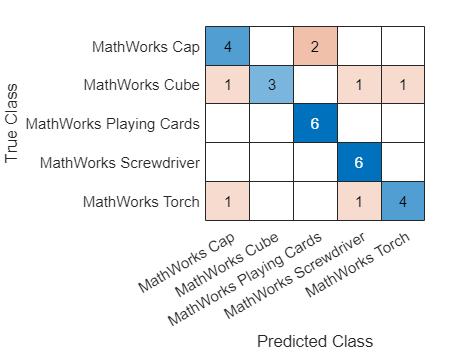

test_labels = testing.Labels;
% write your code on the lines below:
%m_knn = fitcknn(train_example, train_labels , 'NumNeighbors', 3)
m_knn3 = knn_fit(train_examples, train_labels, 3);

%predictions = predict(m_knn, test_examples);
predictions = knn_predict(m_knn3, test_examples);

[c, order] = confusionmat(test_labels, predictions);
confusionchart(test_labels, predictions);

p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 76.6667

## CNN3 -based features

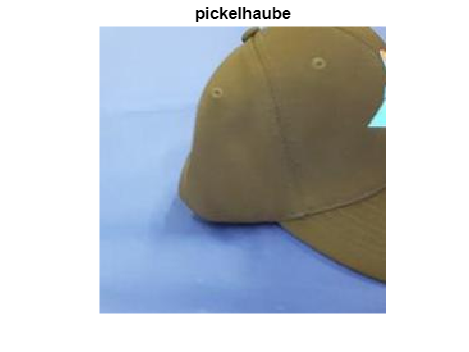

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('Error: Data set MerchData not fond, check the directory.');
end

rng(0); % Good practice to reseed random generator in order to compare results

% loading image datastore MerchData such so folders are included and folder
% names as well
imds = imageDatastore('MerchData','IncludeSubfolders', true, 'LabelSource','foldernames');
% Load pretrained network
net = resnet50();
% Read and Resize Image random image, image 9 in this case
% input size is the image size required for first layer of net 
im = imds.readimage(9);
inputSize = net.Layers(1).InputSize;
im = imresize(im,inputSize(1:2));
%Classify and display the image with the predicted label.
label = classify(net,im);
figure
% display the image with the net predicted title
imshow(im)
title(string(label))

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('Error: Data set MerchData not fond, check the directory.');
end

rng(0); % Good practice to reseed random generator in order to compare results

% loading image datastore MerchData such so folders are included and folder
% names as well
imds = imageDatastore('MerchData','IncludeSubfolders', true, 'LabelSource','foldernames');

imds =   ImageDatastore with properties:

                       Files: {
                              '/MATLAB Drive/MerchData/MerchData/MathWorks Cap/Hat_0.jpg';
                              '/MATLAB Drive/MerchData/MerchData/MathWorks Cap/Hat_123.jpg';
                              '/MATLAB Drive/MerchData/MerchData/MathWorks Cap/Hat_148.jpg'
                               ... and 72 more
                              }
                     Folders: {
                              '/MATLAB Drive/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 72 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


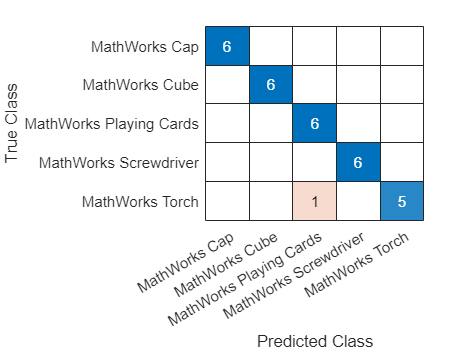

% Load pretrained network
net = resnet50();
%Prepare Training and Test Image Sets by spliting data into 60 and 40
%percents
[trainingSet, testSet] = splitEachLabel(imds, 0.6, 'randomize');
% Pre-process Images For CNN
% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network. Also does color
% processing
imageSize = net.Layers(1).InputSize;
auTraining = augmentedImageDatastore(imageSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
auTesting = augmentedImageDatastore(imageSize, testSet, 'ColorPreprocessing', 'gray2rgb');
%Extract Training Features Using CNN
%fc1000 is a deep convolutional layer and contains high level features
%and is expected to give us high precition  (96.6% in this case)
featureLayer = 'fc1000';
%as we can see lower layers give us lower percentage in general, as
%they have processed fewer amount of data, but they could be more time
%efficinet

%featureLayer = 'add_1';(p=56.6)
%featureLayer = 'add_7';(p=40)
%featureLayer = 'add_16';(p=93.3)

% returns net activations for a specific layer in batch size of 32 and
% outputs it as a rows
trainingFeatures = activations(net, auTraining, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'rows');
testingFeatures = activations(net, auTesting, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'rows');

% getting labels from training and testing data
train_labels = trainingSet.Labels;
test_labels = testSet.Labels;

% built in functions
%m_knn = fitcknn(trainingFeatures, train_labels , 'NumNeighbors', 3)
%predictions = predict(m_knn, testingFeatures);

% using my functions for knn and prediction
m_knn3 = knn_fit(trainingFeatures, train_labels, 3);
predictions = knn_predict(m_knn3, testingFeatures);

% creating confusion matrix for visualisation and outputing percentage of
% accuracy
[c, order] = confusionmat(test_labels, predictions);
confusionchart(test_labels, predictions);

p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 96.6667